# Assignment 2

## initialize

close all;
clc

## 1. parameters

% physical params
g = 9.8

g = 9.8000


% vehicle params
weight = 1807.2 % kg

weight = 1.8072e+03

wheelbase = 2950*10^-3 % mm->m

wheelbase = 2.9500

R_tire = 402*10^-3 % mm->m

R_tire = 0.4020

beta_1 = 3.538

beta_1 = 3.5380

beta_2 = 2.06

beta_2 = 2.0600

beta_3 = 1.404

beta_3 = 1.4040

beta_4 = 1

beta_4 = 1

beta_5 = 0.713

beta_5 = 0.7130

beta_6 = 0.582

beta_6 = 0.5820

beta_dif = 4.1

beta_dif = 4.1000


% engine params
omega_max = 6700*0.1047198 % rpm->rad/s

omega_max = 701.6227

omega_min = 725*0.1047198 % rpm->rad/s, idle

omega_min = 75.9219

yita = 1 % efficiency

yita = 1


% resistance params
%%%%%%%%%%%%%%%%%%%%% it hasn't been done yet%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
mu_R = 1

mu_R = 1

gradient = 0

gradient = 0

A = 3 % m^2

A = 3

rho = 0.1

rho = 0.1000

c_d = 0.5% drag coefficient

c_d = 0.5000


% simulation params
dt = 0.01 % s

dt = 0.0100

## characteristic curve

### param of the curve

% beta 1
v1_max = omega_max/beta_dif/beta_1*R_tire % m/s

v1_max = 19.4441

v1_min = omega_min/beta_dif/beta_1*R_tire % m/s

v1_min = 2.1040

x1 = v1_min:dt:v1_max;
% beta 2
v2_max = omega_max/beta_dif/beta_2*R_tire

v2_max = 33.3948

v2_min = omega_min/beta_dif/beta_2*R_tire

v2_min = 3.6136

x2 = v2_min:dt:v2_max;
% beta 3
v3_max = omega_max/beta_dif/beta_3*R_tire

v3_max = 48.9980

v3_min = omega_min/beta_dif/beta_3*R_tire

v3_min = 5.3020

x3 = v3_min:dt:v3_max;
% beta 4
v4_max = omega_max/beta_dif/beta_4*R_tire

v4_max = 68.7932

v4_min = omega_min/beta_dif/beta_4*R_tire

v4_min = 7.4440

x4 = v4_min:dt:v4_max;
% beta 5
v5_max = omega_max/beta_dif/beta_5*R_tire

v5_max = 96.4842

v5_min = omega_min/beta_dif/beta_5*R_tire

v5_min = 10.4405

x5 = v5_min:dt:v5_max;
% beta 6
v6_max = omega_max/beta_dif/beta_6*R_tire

v6_max = 118.2015

v6_min = omega_min/beta_dif/beta_6*R_tire

v6_min = 12.7905

x6 = v6_min:dt:v6_max;

### formulation

#### resistance formulation

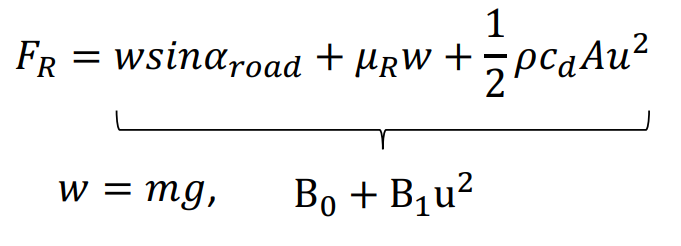

B0 = weight * g * sin(alpha) + mu_R * weight

B0 = 1.8072e+03

B1 = 0.5 * rho * c_d * A

B1 = 0.0750

## torque engine speed

### map

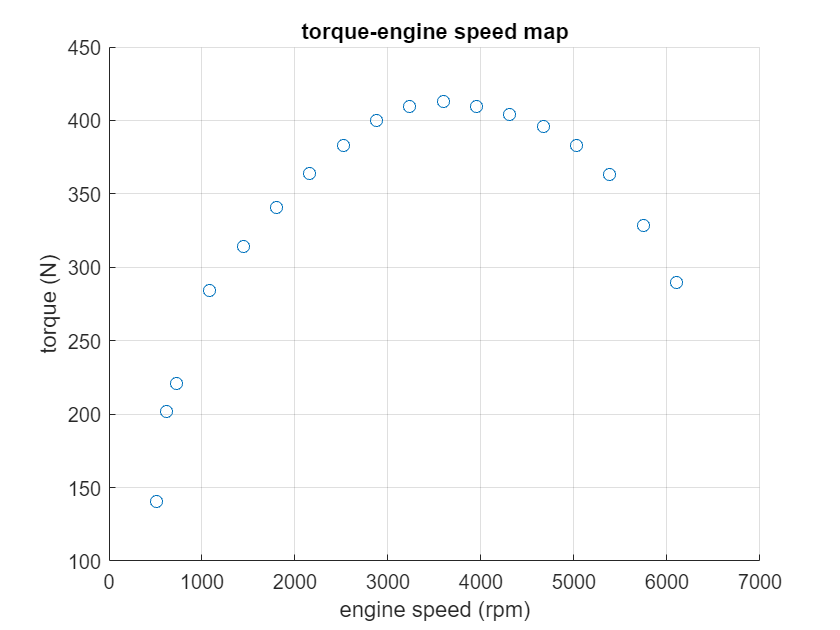

% the data is extracted from the carsim
% map_engine_spped = [400 508 617 725 1083 1442 1800 2158 2517 2875 3233 3592 3950 4308 4667 5025 5383 5742 6100 6500 6700];
% map_torque = [0 140.57 202.03 221.15 284.38 314.16 340.56 363.84 382.8 399.96 409.2 413.16 409.2 403.84 396 382.8 363.32 328.55 289.4 -106.92 -108.24];
map_engine_spped = [508 617 725 1083 1442 1800 2158 2517 2875 3233 3592 3950 4308 4667 5025 5383 5742 6100];
map_torque = [140.57 202.03 221.15 284.38 314.16 340.56 363.84 382.8 399.96 409.2 413.16 409.2 403.84 396 382.8 363.32 328.55 289.4];
scatter(map_engine_spped,map_torque)
title("torque-engine speed map");
xlabel("engine speed (rpm)");
ylabel("torque (N)");
grid on;

### poly fit

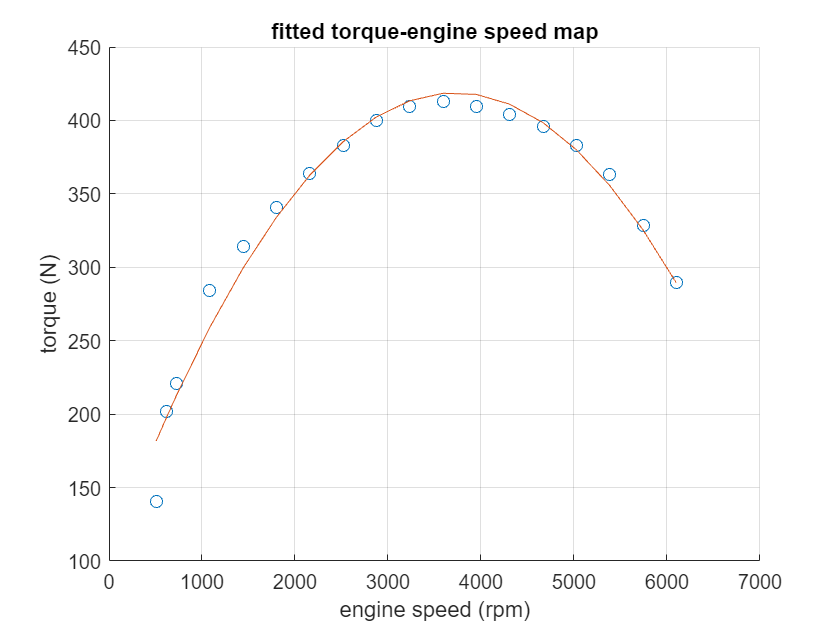

[p,ErrorEst] = polyfit(map_engine_spped,map_torque,2);
hold on;
title("fitted torque-engine speed map");
pop_fit = polyval(p,map_engine_spped,ErrorEst);
plot(map_engine_spped,pop_fit)